# Ray-Based WCC Workspace Analysis 

clear;

## 1) 2-DoF point mass CDPR

### Load the robot 

Load the 2 DoF robot in the manner shown in `T1_load_robot.mlx`.

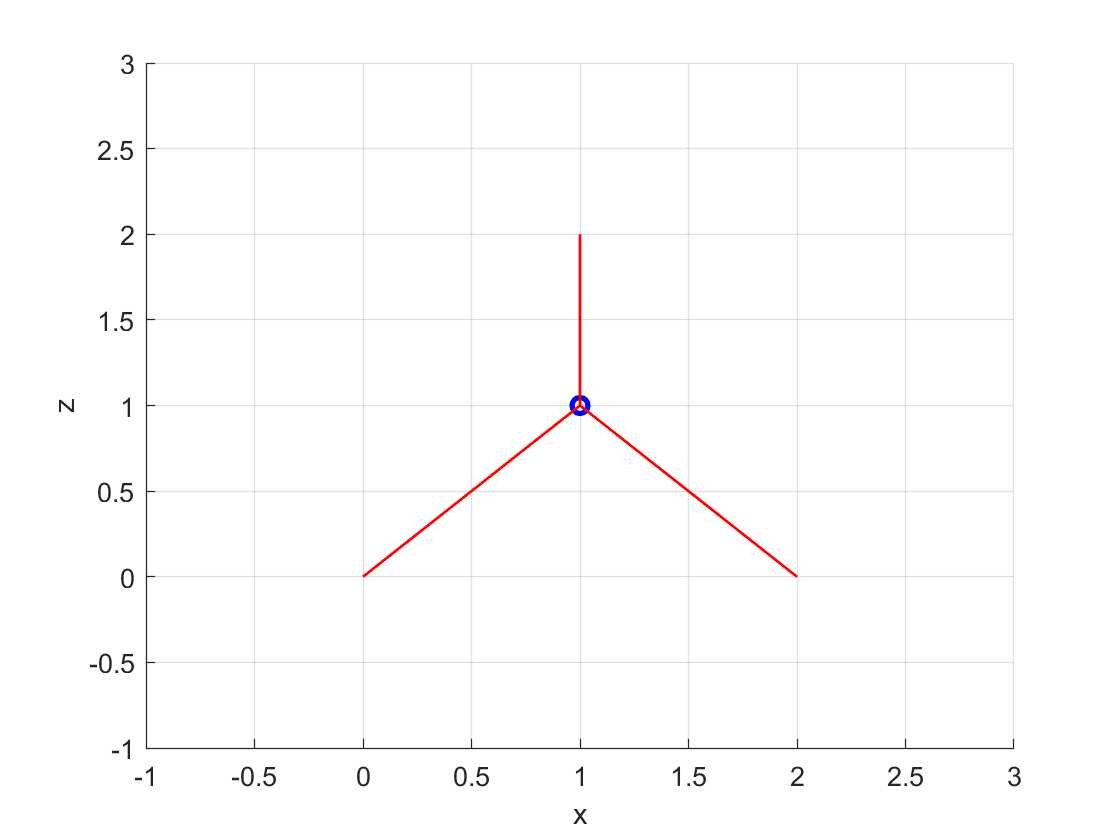

model_config_2_DoF = ModelConfig('Example point mass XZ');
cdpr_model_2_DoF = model_config_2_DoF.getModel('3_cables'); % , [], ModelModeType.COMPILED); % Compiled mode needs to fix the plotting TODO
MotionSimulatorBase.PlotFrame(cdpr_model_2_DoF, model_config_2_DoF.displayRange, model_config_2_DoF.viewAngle); % Plot robot

### Setup the grid

A uniform (equal spacing) grid will be setup representing the set of points which the workspace analysis will be run.

% Set up the workspace simulator
% First the grid
q_min_2_DoF             = [0.05; -2.0];
q_max_2_DoF             = [1.95; 1.95];
q_step_2_DoF            = 0.05*ones(cdpr_model_2_DoF.numDofs, 1); 
uniform_grid_2_DoF      = UniformGrid(q_min_2_DoF, q_max_2_DoF, q_step_2_DoF, 'step_size');

### Setup plotting

dofs_to_plot_2_DoF      = [1 2]; % Plot X axis as first DoF and Y axis as second DoF

### Setup and run workspace simulator

The `PointWorkspaceSimulator` allows the point-wise workspace to be run. In this example, the static workspace will be first computed:

ws_condition_wcc_3_DoF = WrenchClosureRayCondition(cdpr_model_2_DoF, 1);

Create the simulator object using the robot model, grid and workspace condition(s):

ws_sim_2_DoF = RayWorkspaceSimulator(cdpr_model_2_DoF, uniform_grid_2_DoF, {ws_condition_wcc_3_DoF}, []);

Run the simulator over the specified grid:

ws_sim_2_DoF.run();

[INFO] Workspace DoF 1. Workspace ray 1. Completion Percentage: 0.84.
[INFO] Workspace DoF 1. Workspace ray 2. Completion Percentage: 1.68.
[INFO] Workspace DoF 1. Workspace ray 3. Completion Percentage: 2.52.
[INFO] Workspace DoF 1. Workspace ray 4. Completion Percentage: 3.36.
[INFO] Workspace DoF 1. Workspace ray 5. Completion Percentage: 4.20.
[INFO] Workspace DoF 1. Workspace ray 6. Completion Percentage: 5.04.
[INFO] Workspace DoF 1. Workspace ray 7. Completion Percentage: 5.88.
[INFO] Workspace DoF 1. Workspace ray 8. Completion Percentage: 6.72.
[INFO] Workspace DoF 1. Workspace ray 9. Completion Percentage: 7.56.
[INFO] Workspace DoF 1. Workspace ray 10. Completion Percentage: 8.40.
[INFO] Workspace DoF 1. Workspace ray 11. Completion Percentage: 9.24.
[INFO] Workspace DoF 1. Workspace ray 12. Completion Percentage: 10.08.
[INFO] Workspace DoF 1. Workspace ray 13. Completion Percentage: 10.92.
[INFO] Workspace DoF 1. Workspace ray 14. Completion Percentage: 11.76.
[INFO] Works

Finally, plot the resulting 2-D workspace:

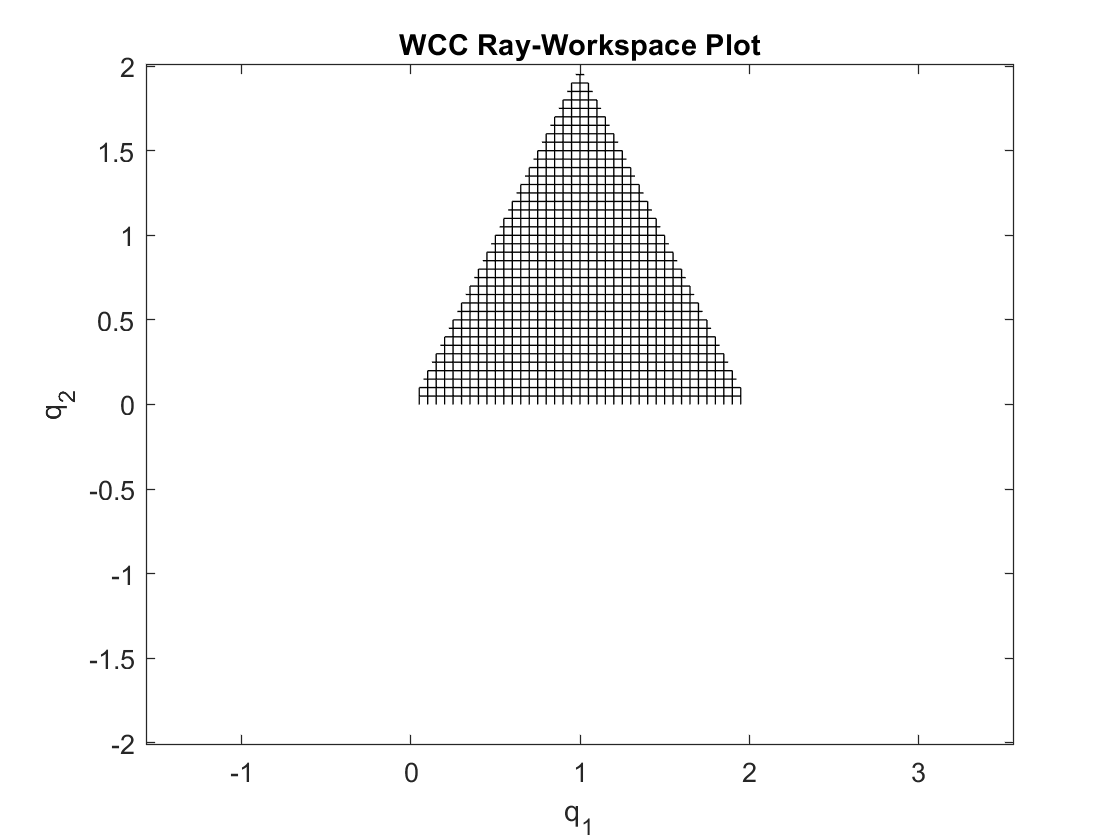

ws_sim_2_DoF.workspace.plotRayWorkspace(dofs_to_plot_2_DoF);
axis equal;
title('WCC Ray-Workspace Plot'); 

## 2) 3-DoF planar CDPR

### Load the robot 

Load the 3 DoF robot as shown in `T1_load_robot.mlx`. 

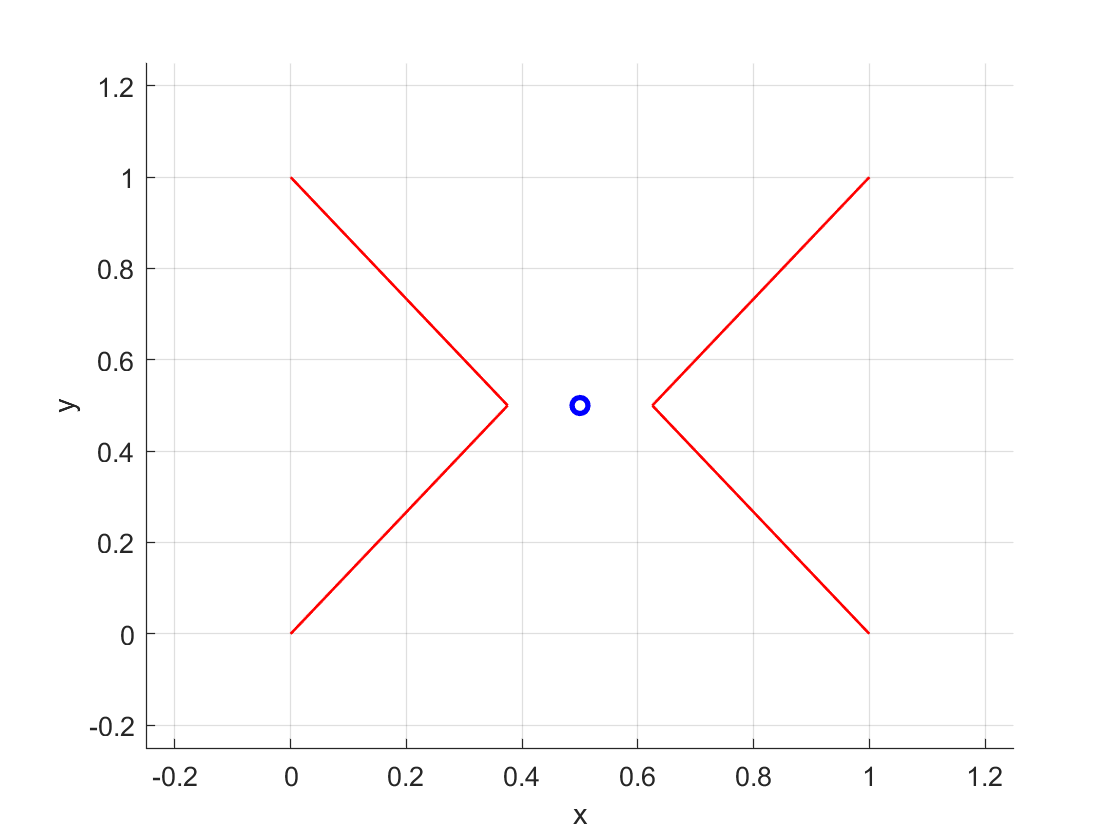

model_config_3_DoF = ModelConfig('Example planar XY');
cdpr_model_3_DoF = model_config_3_DoF.getModel('basic');
MotionSimulatorBase.PlotFrame(cdpr_model_3_DoF, model_config_3_DoF.displayRange, model_config_3_DoF.viewAngle); % Plot robot

### Setup the grid

A uniform (equal spacing) grid will be setup representing the set of points which the workspace analysis will be run.

% Set up the workspace simulator
% First the grid
q_min_3_DoF             = [0.02; 0.02; -pi/4];
q_max_3_DoF             = [0.98; 0.98; pi/4];
q_step_3_DoF            = [0.02; 0.02; pi/20]; 
uniform_grid_3_DoF      = UniformGrid(q_min_3_DoF, q_max_3_DoF, q_step_3_DoF, 'step_size');

### Setup plotting

dofs_to_plot_3_DoF      = [1 2 3]; % Plot X axis as first DoF and Y axis as second DoF

### Setup and run workspace simulator

The `PointWorkspaceSimulator` allows the point-wise workspace to be run. In this example, the static workspace will be first computed:

ws_condition_wcc_3_DoF = WrenchClosureRayCondition(cdpr_model_3_DoF, 1);

Create the simulator object using the robot model, grid and workspace condition(s):

ws_sim_3_DoF = RayWorkspaceSimulator(cdpr_model_3_DoF, uniform_grid_3_DoF, {ws_condition_wcc_3_DoF}, []);

Run the simulator over the specified grid:

ws_sim_3_DoF.run();

[INFO] Workspace DoF 1. Workspace ray 1. Completion Percentage: 0.03.
[INFO] Workspace DoF 1. Workspace ray 2. Completion Percentage: 0.06.
[INFO] Workspace DoF 1. Workspace ray 3. Completion Percentage: 0.09.
[INFO] Workspace DoF 1. Workspace ray 4. Completion Percentage: 0.11.
[INFO] Workspace DoF 1. Workspace ray 5. Completion Percentage: 0.14.
[INFO] Workspace DoF 1. Workspace ray 6. Completion Percentage: 0.17.
[INFO] Workspace DoF 1. Workspace ray 7. Completion Percentage: 0.20.
[INFO] Workspace DoF 1. Workspace ray 8. Completion Percentage: 0.23.
[INFO] Workspace DoF 1. Workspace ray 9. Completion Percentage: 0.26.
[INFO] Workspace DoF 1. Workspace ray 10. Completion Percentage: 0.29.
[INFO] Workspace DoF 1. Workspace ray 11. Completion Percentage: 0.32.
[INFO] Workspace DoF 1. Workspace ray 12. Completion Percentage: 0.34.
[INFO] Workspace DoF 1. Workspace ray 13. Completion Percentage: 0.37.
[INFO] Workspace DoF 1. Workspace ray 14. Completion Percentage: 0.40.
[INFO] Workspac

Finally, plot the resulting 2-D workspace:

### Plotting the workspace

First, plot the complete 3-D workspace:

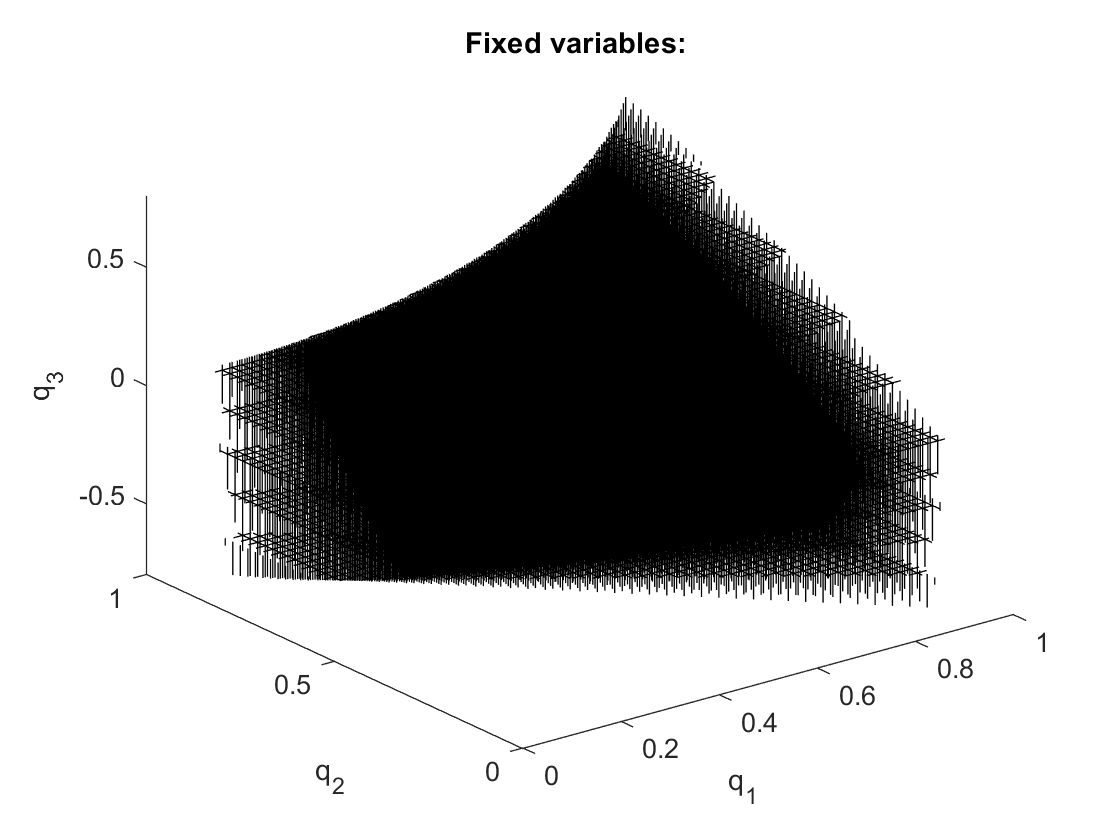

ws_sim_3_DoF.workspace.plotRayWorkspace([1 2 3]);
axis([0 1 0 1 -0.8 0.8]);

In addition to the 3-D workspace, it is possible to plot 2-D cross sections of the workspace. The indices [1 2] specify to plot the q_1 vs q_2 cross-section for q_3 = 0:

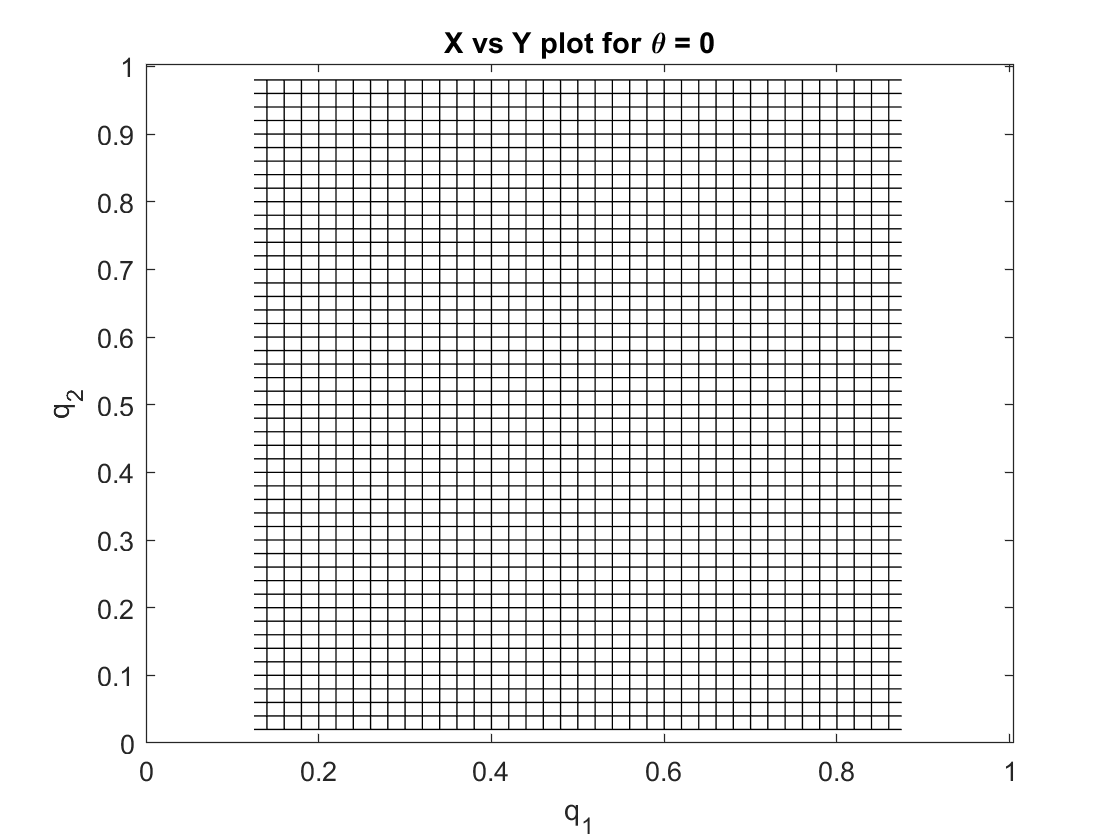

fixed_values = [0; 0; 0];
ws_sim_3_DoF.workspace.plotRayWorkspace([1 2], fixed_values);
title('X vs Y plot for \theta = 0');

The q_1 vs q_2 cross-section for q_3 = pi/20:

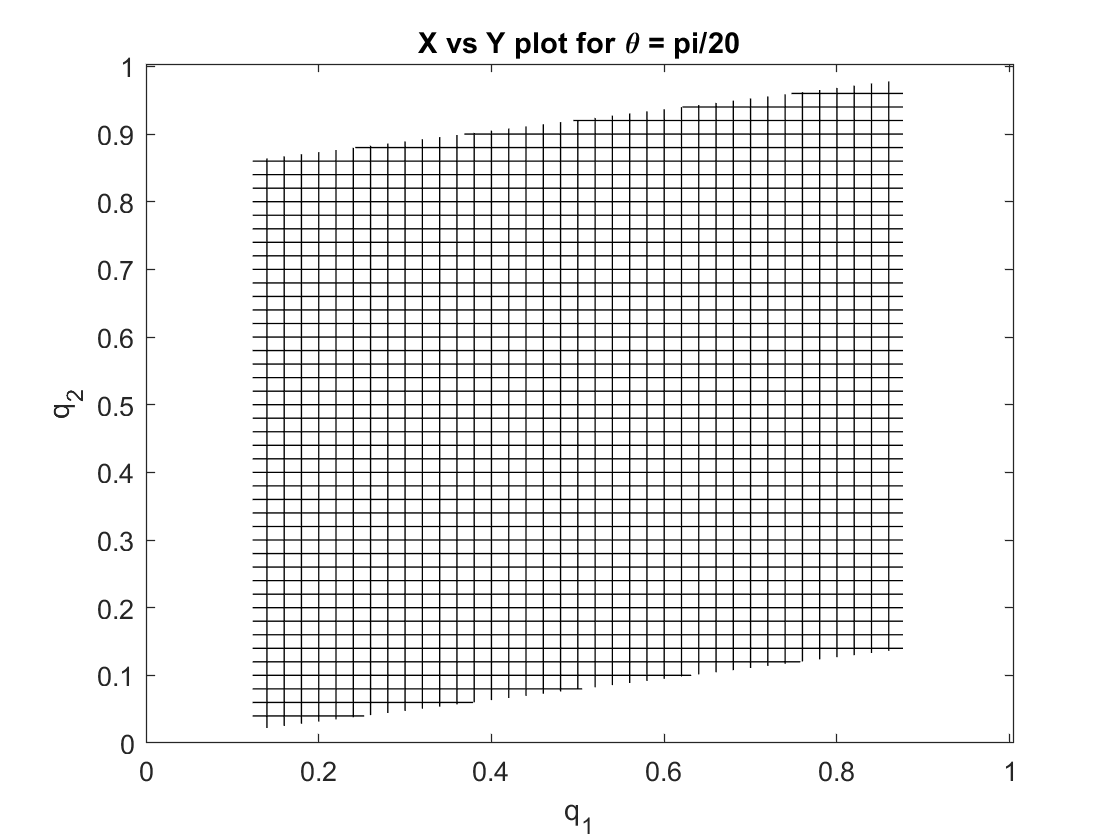

fixed_values = [0; 0; pi/20];
ws_sim_3_DoF.workspace.plotRayWorkspace([1 2], fixed_values);
title('X vs Y plot for \theta = pi/20');

The q_1 vs q_2 cross-section for q_3 = pi/10:

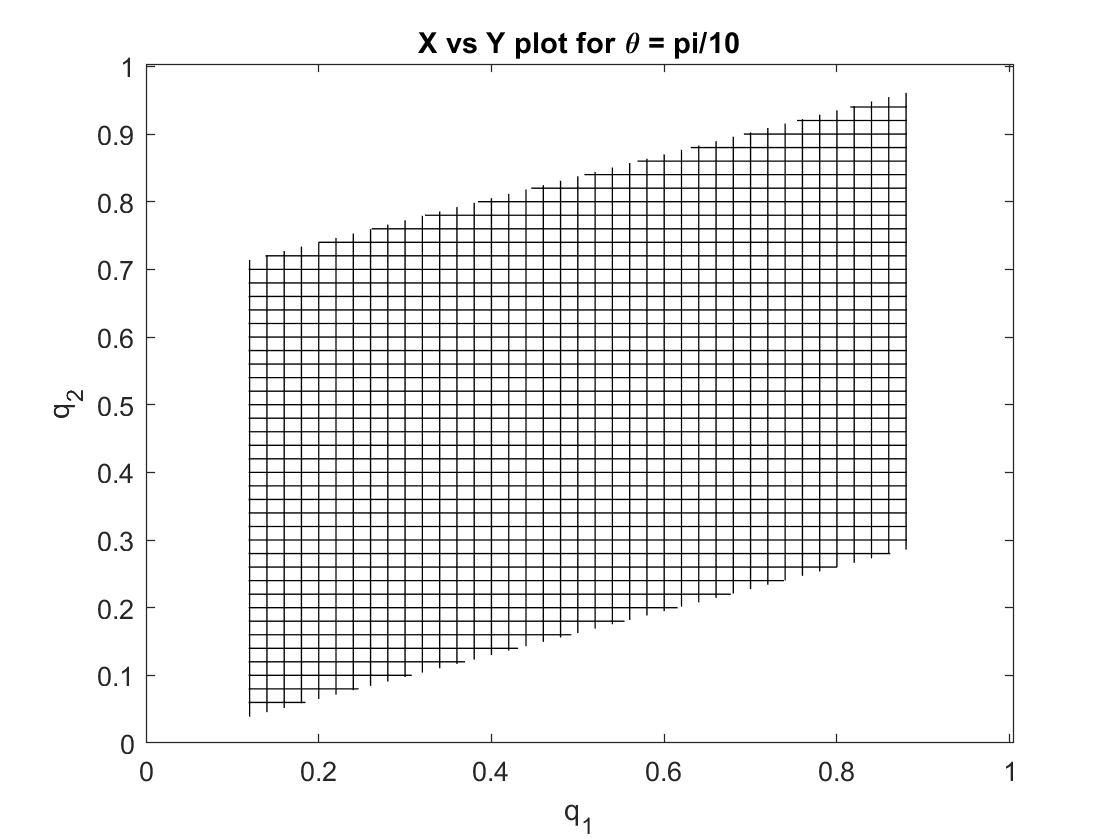

fixed_values = [0; 0; pi/10];
ws_sim_3_DoF.workspace.plotRayWorkspace([1 2], fixed_values);
title('X vs Y plot for \theta = pi/10');

The q_1 vs q_2 cross-section for q_3 = -pi/20:

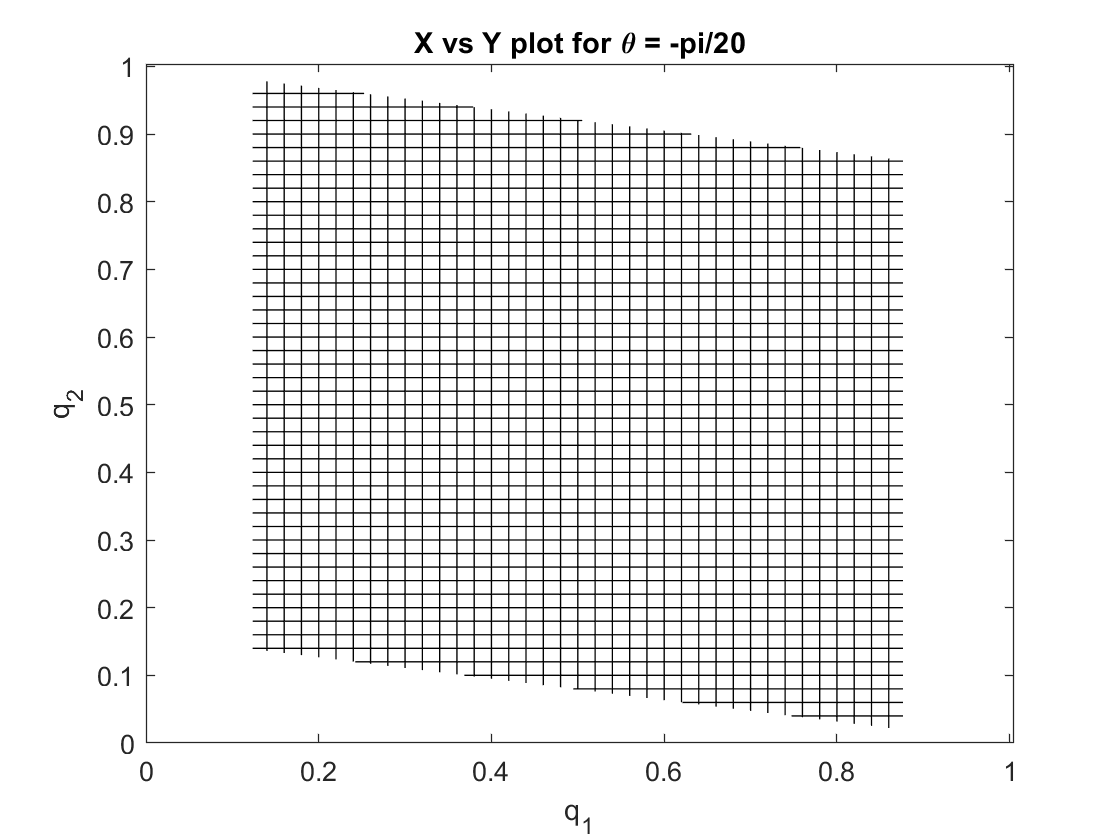

fixed_values = [0; 0; -pi/20];
ws_sim_3_DoF.workspace.plotRayWorkspace([1 2], fixed_values);
title('X vs Y plot for \theta = -pi/20');

And also q_1 vs q_2 cross-section for q_3 = -pi/10:

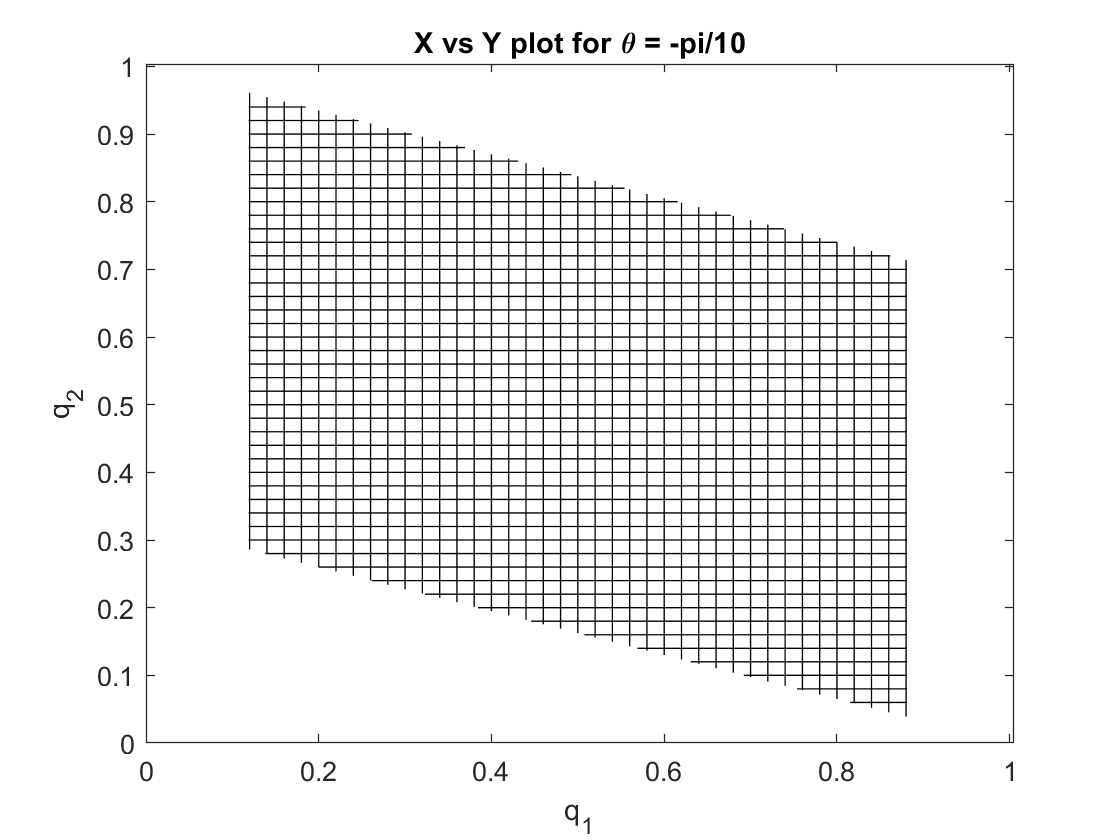

fixed_values = [0; 0; -pi/10];
ws_sim_3_DoF.workspace.plotRayWorkspace([1 2], fixed_values);
title('X vs Y plot for \theta = -pi/10');

Alternatively, the q_1 vs q_3 cross section can be plotted too:

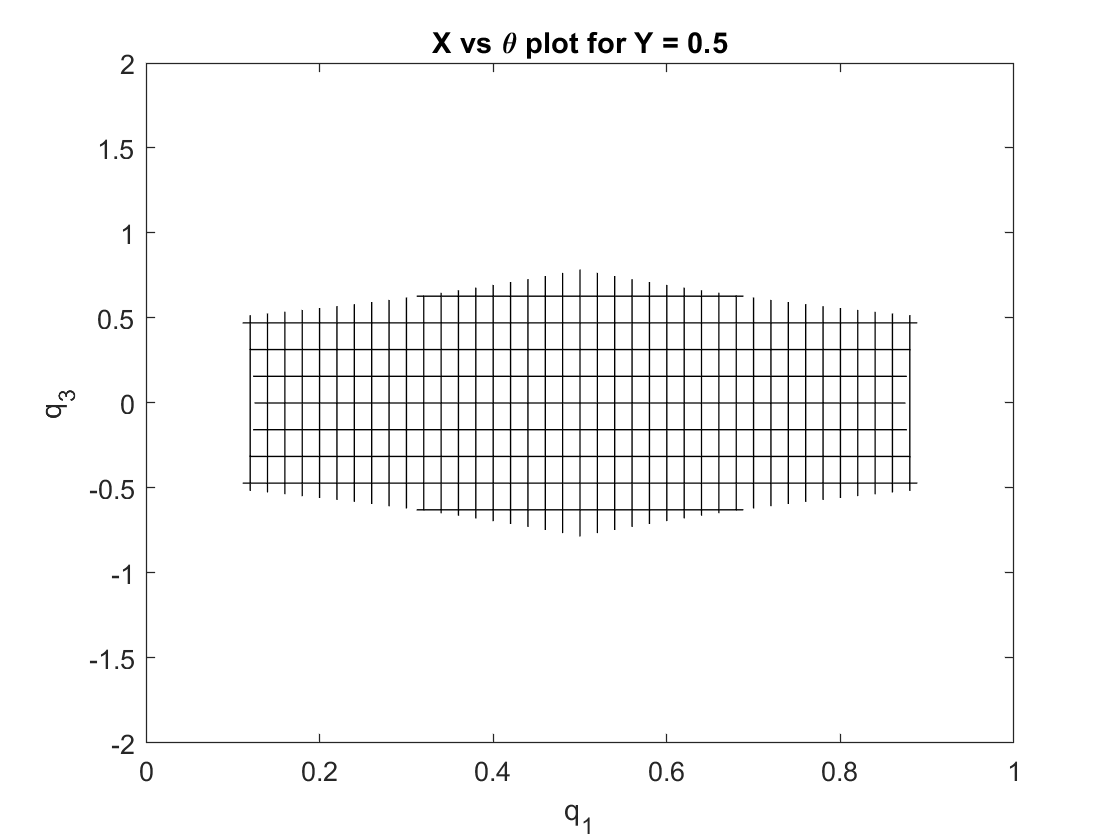

fixed_values = [0; 0.5; 0];
ws_sim_3_DoF.workspace.plotRayWorkspace([1 3], fixed_values);
axis([0 1 -2.0 2.0]);
title('X vs \theta plot for Y = 0.5');

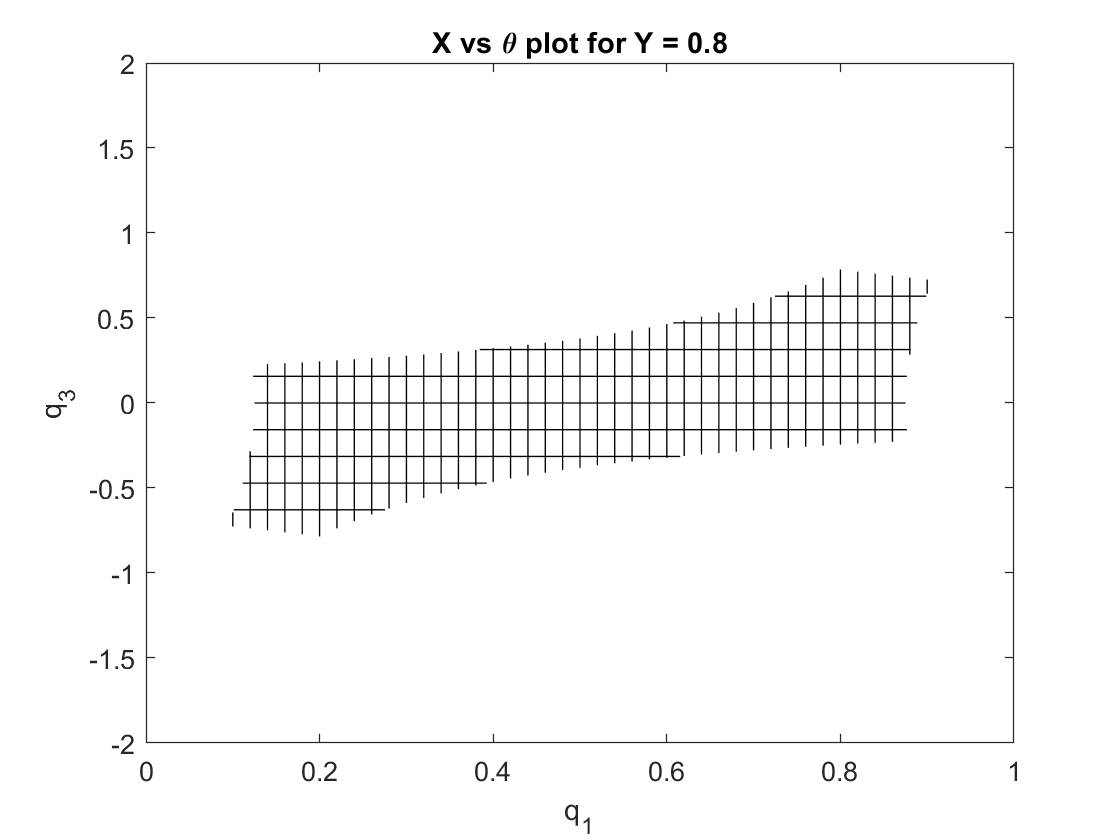

fixed_values = [0; 0.8; 0];
ws_sim_3_DoF.workspace.plotRayWorkspace([1 3], fixed_values);
axis([0 1 -2.0 2.0]);
title('X vs \theta plot for Y = 0.8');